segmentationUsingSkeletonProceesing

%打算是对mask的骨架进行处理，参考：we pruned small lateral branches that came up in the skeleton. Then, we identified all crossing points in the skeleton by using the fact that crossing points are the only skeleton points that possess more than 2 neighbors.https://ieeexplore.ieee.org/document/5378409/references#references

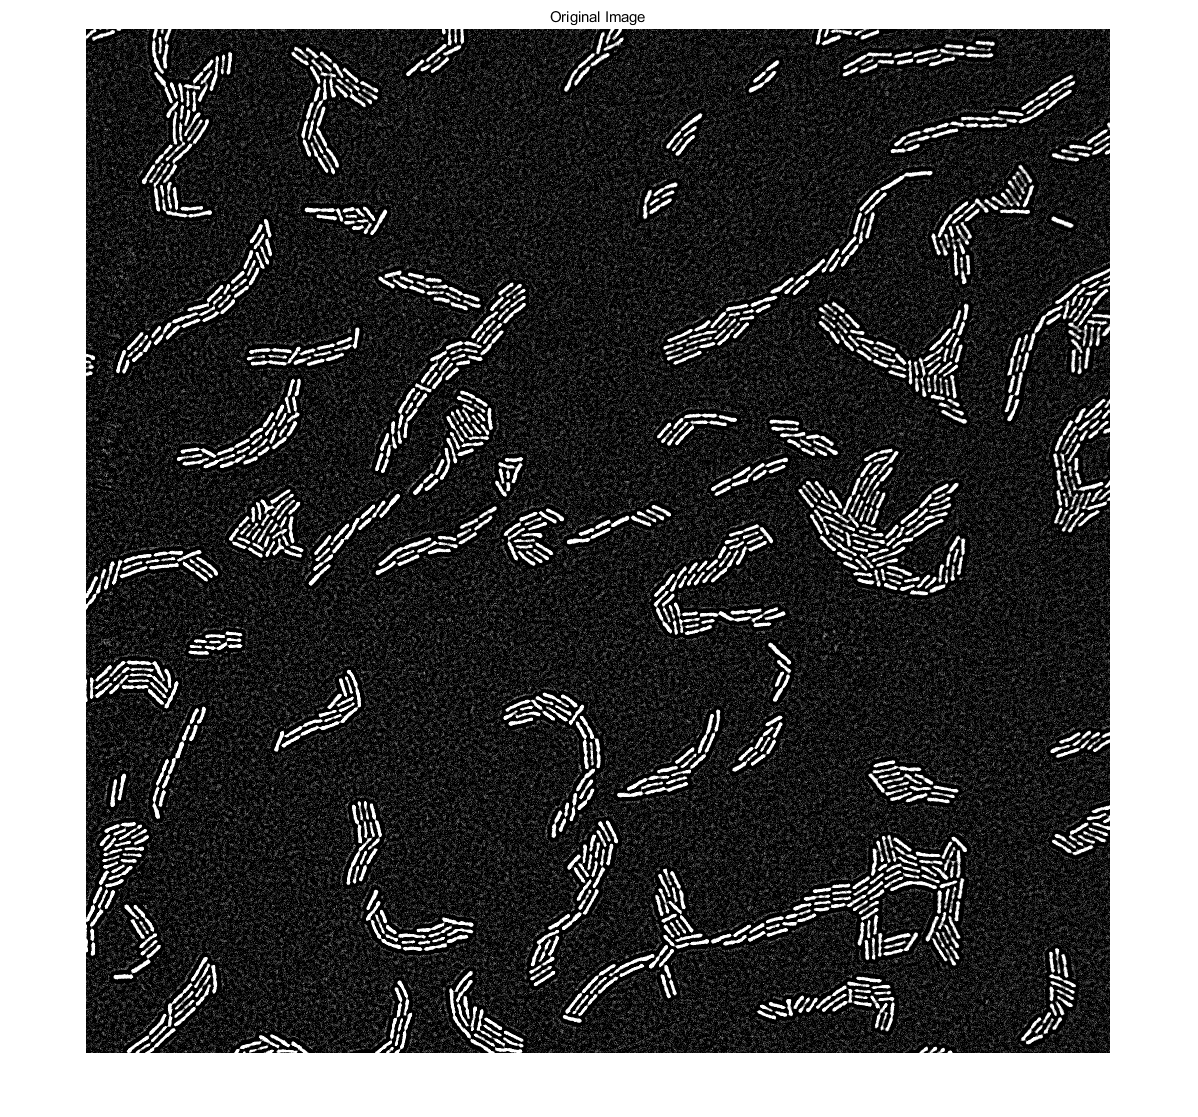

image=import_tiff_stack('E:\2019-12-26 PAO1_deltpslpelfliC_IP32_100x ys\field0004\BF\imageBF04000.tif');
I=image;
se = strel('disk',2);
Io = imopen(I,se);
imshow(I), title('Original Image')

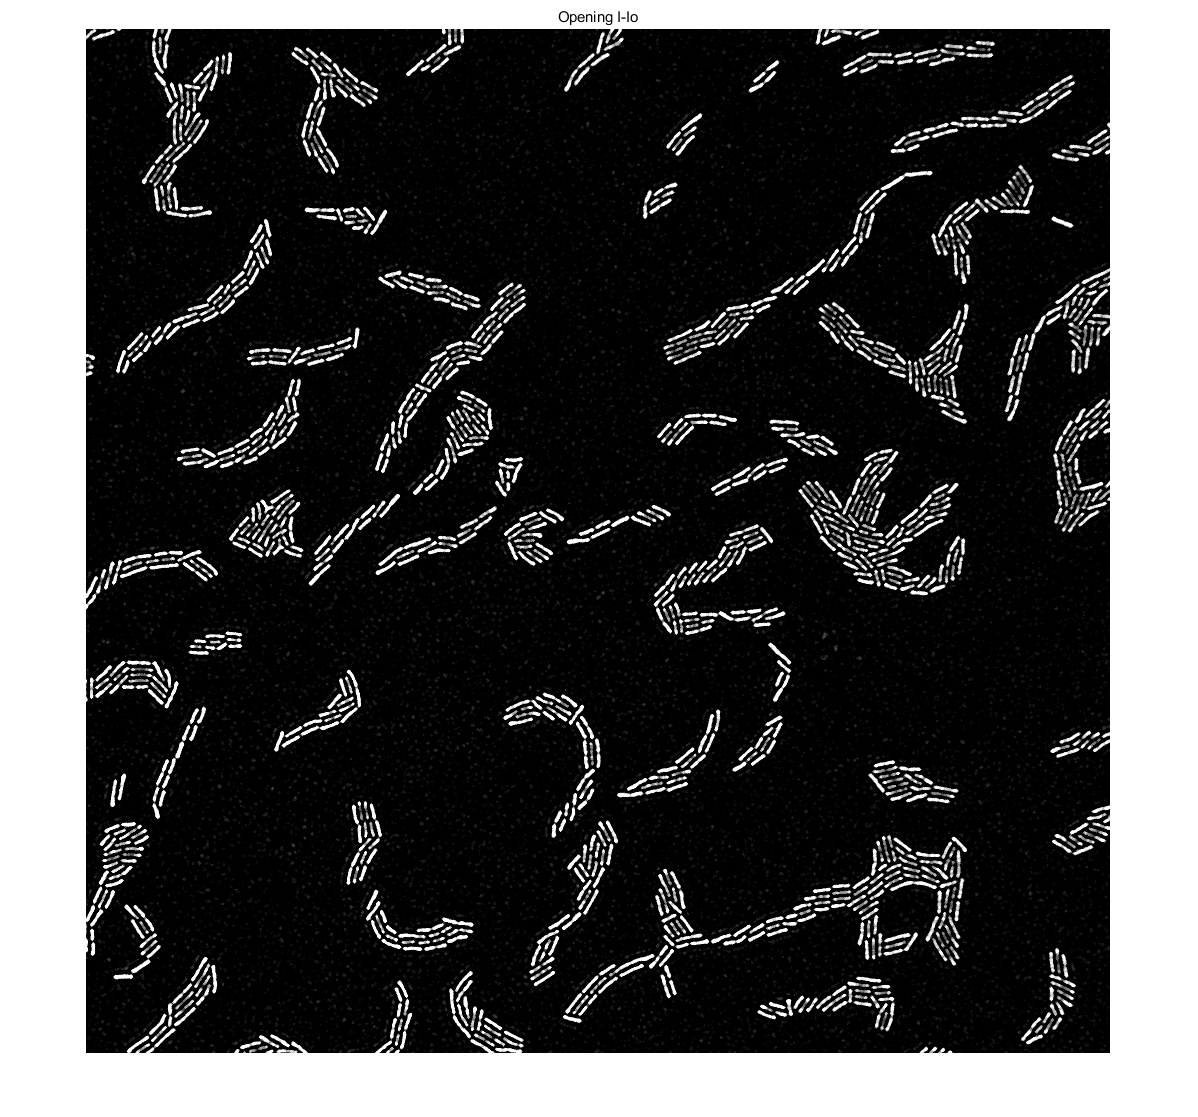

imshow(Io),title('Opening I-Io')

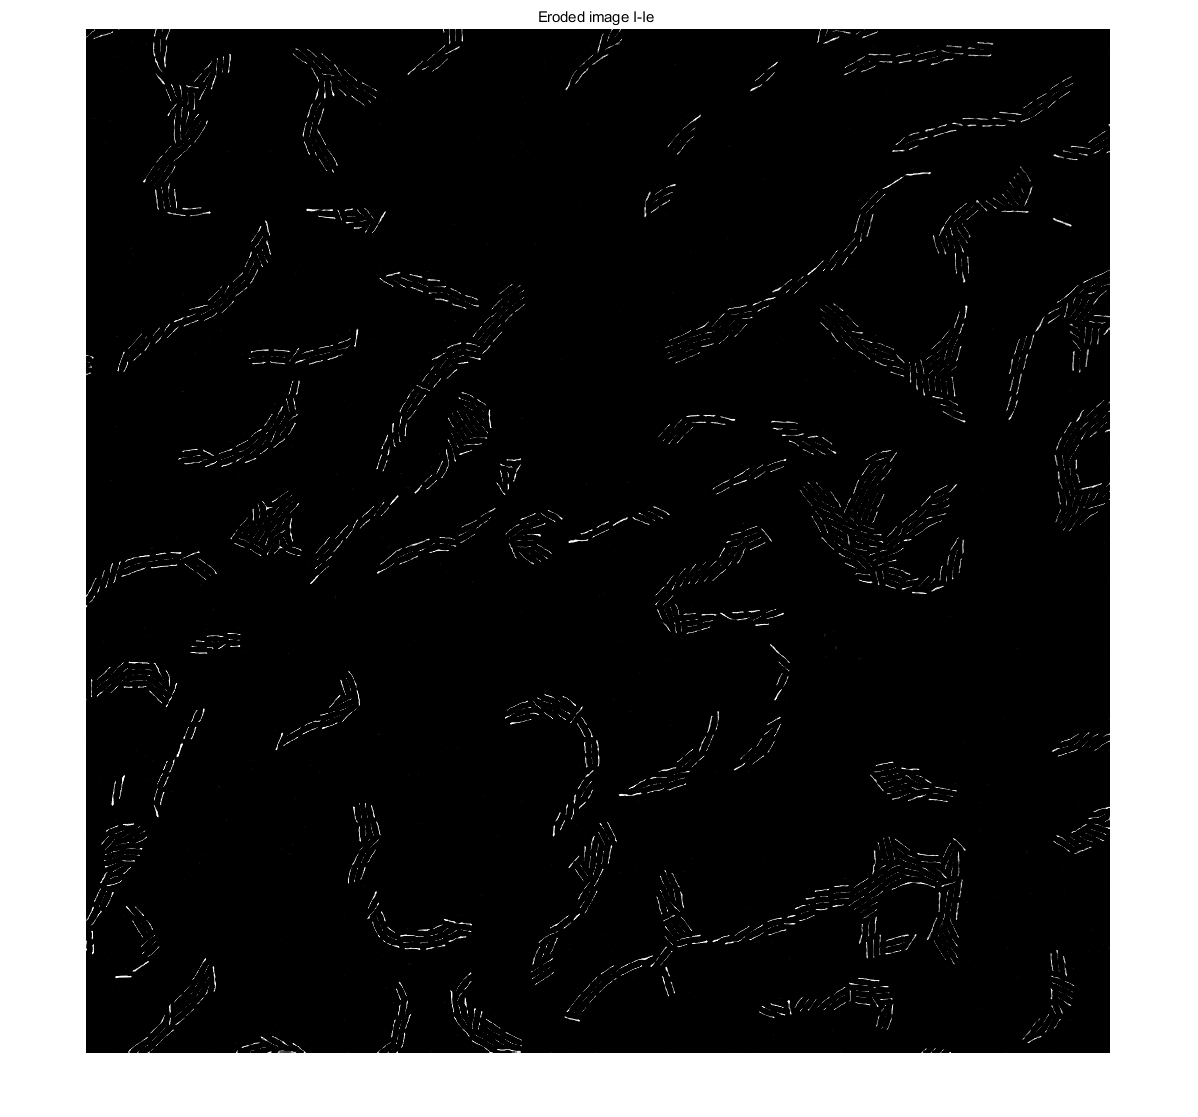


Ie = imerode(Io,strel('disk',3));
imshow(Ie), title('Eroded image I-Ie ')

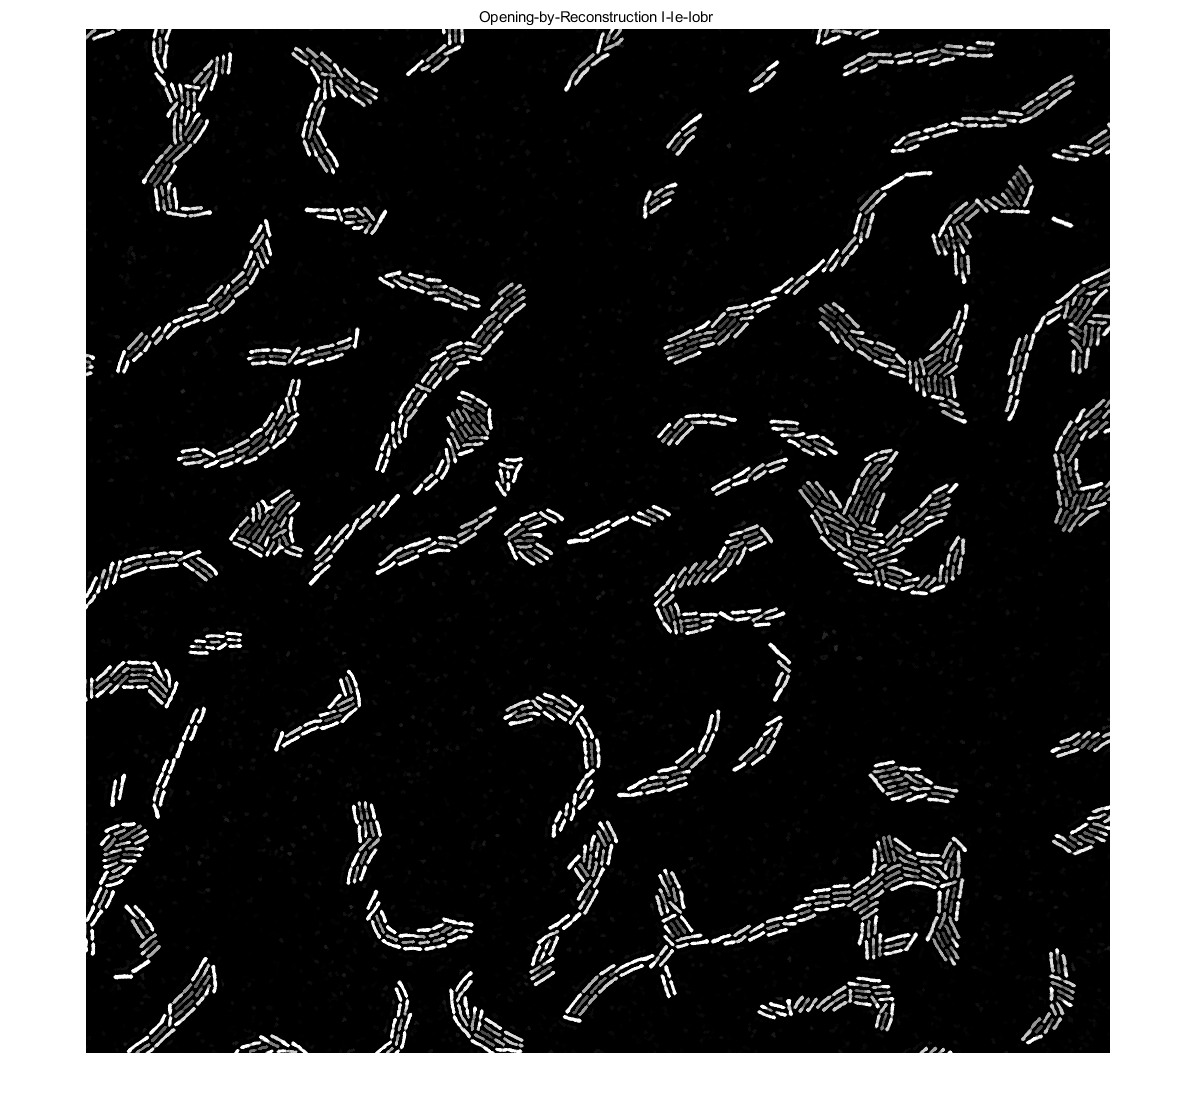

Iobr = imreconstruct(Ie,Io);
imshow(Iobr),title('Opening-by-Reconstruction I-Ie-Iobr ')

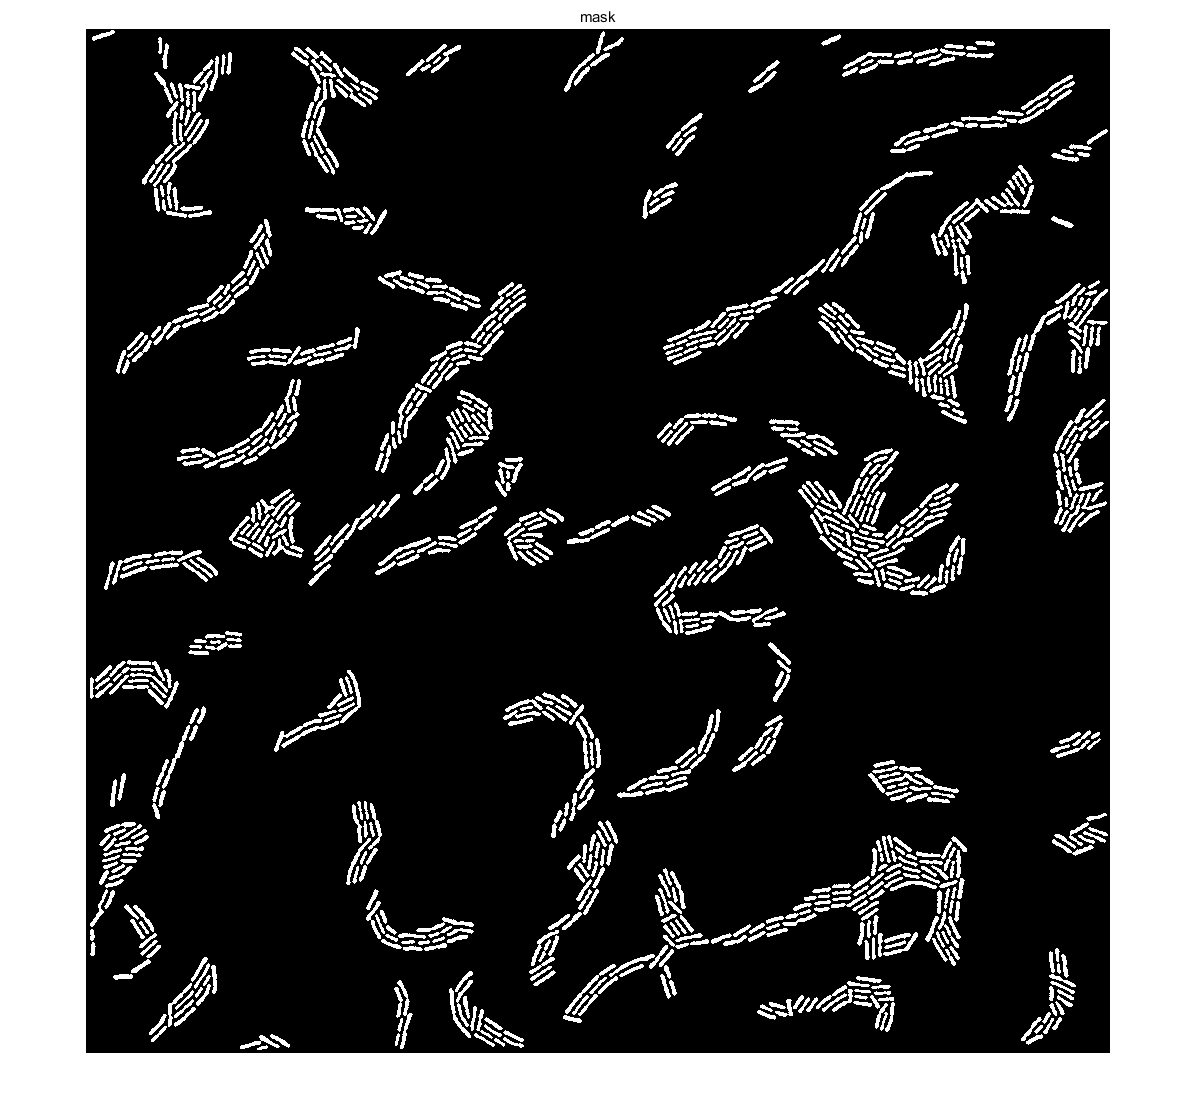


[bw,~]=myImageProcessing_cBFys(Iobr,'w');
% parameter
% % grayThresh=40;
% % areaThreshold=100;  % proper 60, overlap 60+40
% % maxIntensity=45;
imshow(bw),title('mask')

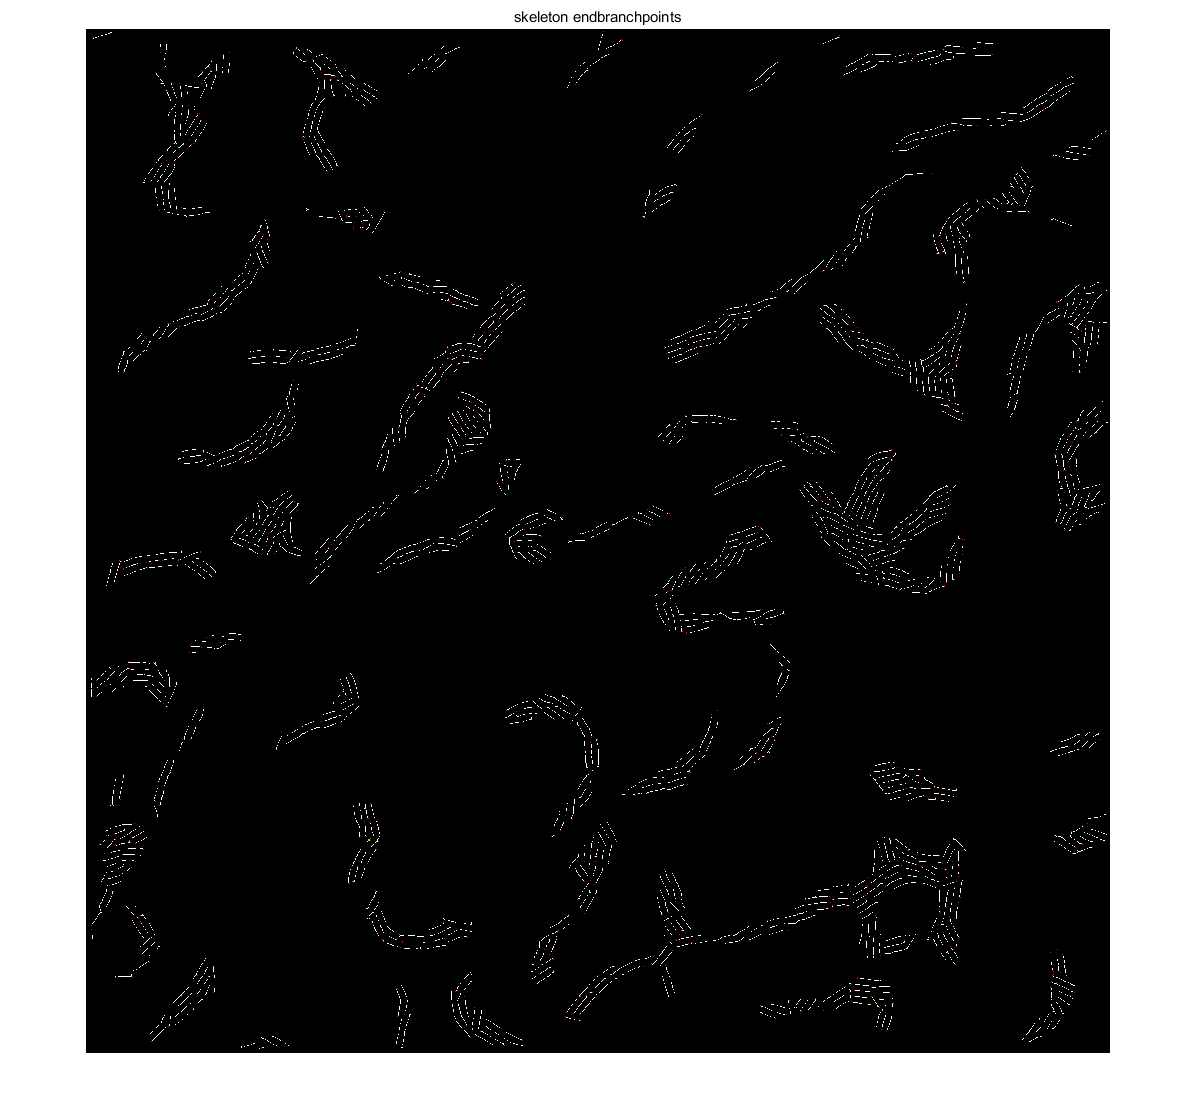

skel = bwmorph(bw,'skel',Inf);
% imshow(skel),title('skeleton')
B = bwmorph(skel, 'branchpoints');
E = bwmorph(skel, 'endpoints');
overlay1 = imoverlay(skel, B, [.3 1 .3]);
% imshow(overlay1)
overlay2 = imoverlay(overlay1, E, [1 0 0]);
imshow(overlay2), title('skeleton endbranchpoints')

[https://ww2.mathworks.cn/matlabcentral/answers/88284-remove-the-spurious-edge-of-skeleton](https://ww2.mathworks.cn/matlabcentral/answers/88284-remove-the-spurious-edge-of-skeleton) 对骨架进行处理，先修剪分支

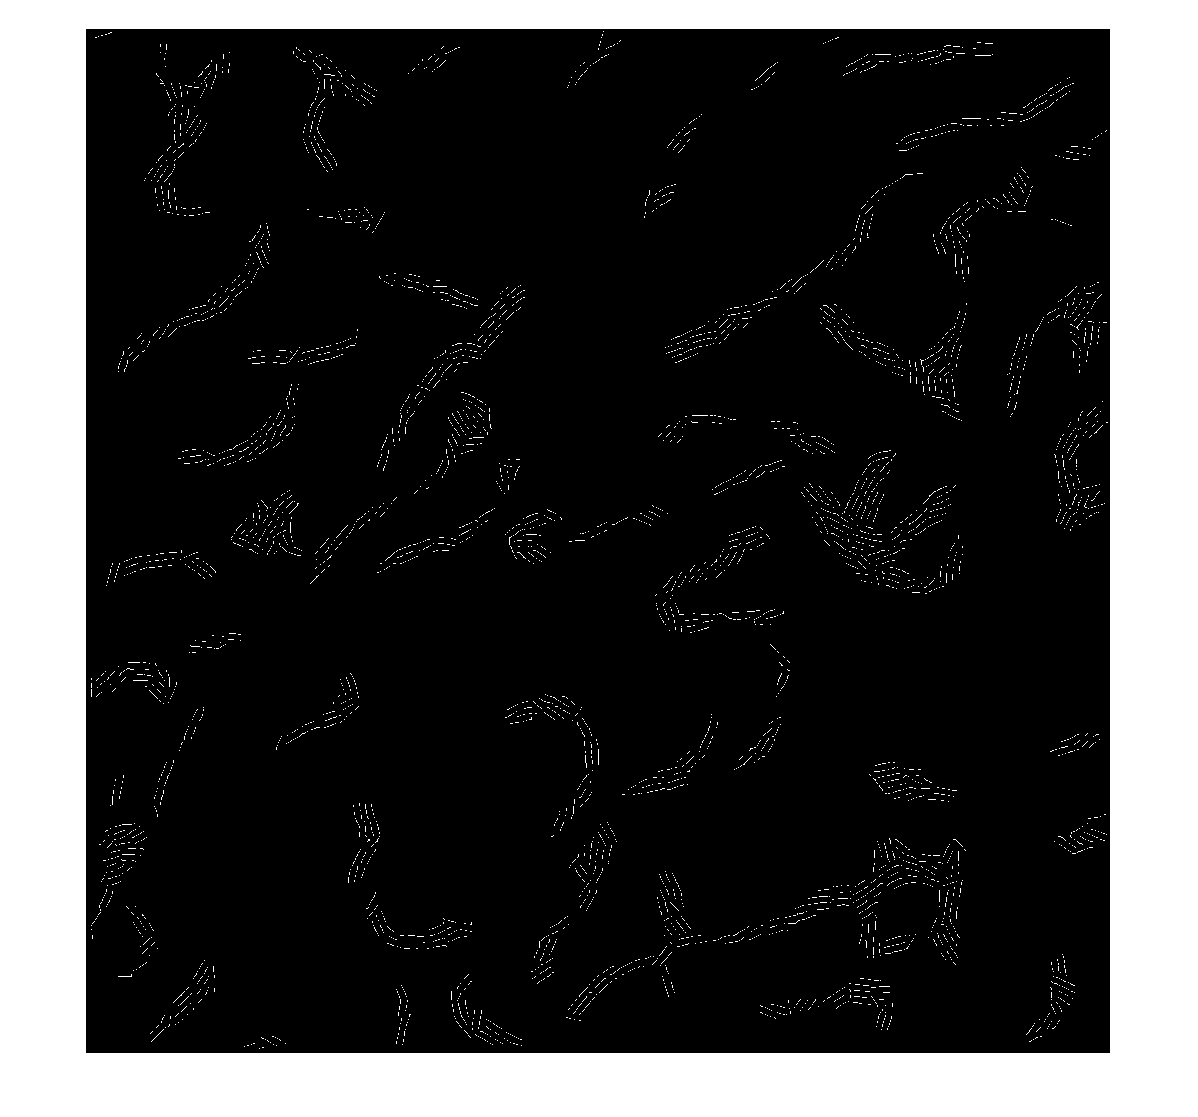


stats = regionprops(skel,'PixelIdxList','PixelList');
% skelNew=false(size(skel));
skelNew=skel;
skelNew2=skel;
for i=1:numel(stats)    
    skelNew(stats(i).PixelIdxList)=false;
    skelNew2(stats(i).PixelIdxList)=false;
    %xy是反的
    smallRegion=[min(stats(i).PixelList);max(stats(i).PixelList)];
    smallImSize=smallRegion(2,:)-smallRegion(1,:)+1;
    smallSkel=false(smallImSize(2),smallImSize(1));
    smallPixelList=stats(i).PixelList-min(stats(i).PixelList)+1;
    for j=1:size(smallPixelList,1)
        smallSkel(smallPixelList(j,2),smallPixelList(j,1))=true;
    end
    B = bwmorph(smallSkel, 'branchpoints');
    E = bwmorph(smallSkel, 'endpoints');
    [y,x] = find(E);
    B_loc = find(B);
    Dmask = false(size(smallSkel));
    %     overlay1 = imoverlay(smallSkel, B, [.3 1 .3]);
    %     overlay2= imoverlay(overlay1, E, [1 0 0]);
    %     figure,imshow(overlay2)
    
    %修剪分支
    for k = 1:numel(x)
        D = bwdistgeodesic(smallSkel,x(k),y(k));
        distanceToBranchPt = min(D(B_loc));
        if distanceToBranchPt<5 %set cut distance from endpoints to branchpoints
            Dmask(D < distanceToBranchPt) =true;
        end
    end
    skelD = smallSkel - Dmask;
    %     figure,imshow(skelD);
    %     hold all;
    %     [y,x] = find(B); plot(x,y,'ro')
    tempBW=false(size(skel));
    tempBW(smallRegion(1,2):smallRegion(2,2),smallRegion(1,1):smallRegion(2,1))=skelD;
    skelNew=skelNew|tempBW;
    
    %     skelD1=skelD & (B | E);% 准备直接用线连起来 重组细菌的骨架
    %     B1 = bwmorph(skelD, 'branchpoints');
    E1 = bwmorph(skelD, 'endpoints');
    B1 = B-E1;
    B1(B1<0)=0;
    skelD1=B1 | E1;
    if sum(B1(:))==0
        [Ey,Ex] = find(E1);
        lineMatrix = zeros(1,2*size(Ex,1));
        lineMatrix(1, 1:2:end) = Ex;
        lineMatrix(1, 2:2:end) = Ey;
        skelD2 = insertShape(uint8(skelD1),'line',lineMatrix,'LineWidth',1);
    else
        [Ey,Ex] = find(E1);
        [By,Bx] = find(B1);
        B1_loc = find(B1);
        if sum(B1(:))==1
            lineMatrix = zeros(size(Ex,1),4);
            lineMatrix(1:end,1) = Ex;
            lineMatrix(1:end,2) = Ey;
            lineMatrix(1:end,3) = Bx;
            lineMatrix(1:end,4) = By;
            skelD2 = insertShape(uint8(skelD1),'line',lineMatrix,'LineWidth',1);
        else
            lineMatrix1=zeros(numel(Ex),4);
            for k = 1:numel(Ex)
                D = dist([Ex(k), Ey(k)], [Bx'; By']);
                Index = find(D==min(D));
                lineMatrix1(k,:) = [Ex(k), Ey(k), Bx(Index), By(Index)];
            end
            lineMatrix2 = zeros(1,2*size(Bx,1));
            lineMatrix2(1, 1:2:end) = Bx;
            lineMatrix2(1, 2:2:end) = By;
            skelD2 = insertShape(uint8(skelD1),'line',lineMatrix1,'LineWidth',1);
            skelD2 = insertShape(uint8(skelD2),'line',lineMatrix2,'LineWidth',1);
        end
        
    end
%     [Ey,Ex] = find(skelD1);
%     lineMatrix = zeros(1,2*size(Ex,1));
%     lineMatrix(1, 1:2:end) = Ex;
%     lineMatrix(1, 2:2:end) = Ey;
%     skelD2 = insertShape(uint8(skelD1),'line',lineMatrix,'LineWidth',1);
    skelD2=logical(skelD2(:,:,1));
    skelD2 = bwmorph(skelD2,'skel',Inf);
    %     figure, imshow(skelD2)
    tempBW=false(size(skel));
    tempBW(smallRegion(1,2):smallRegion(2,2),smallRegion(1,1):smallRegion(2,1))=skelD2;
    skelNew2=skelNew2|tempBW;
end

imshow(skelNew),title ('skelNew')

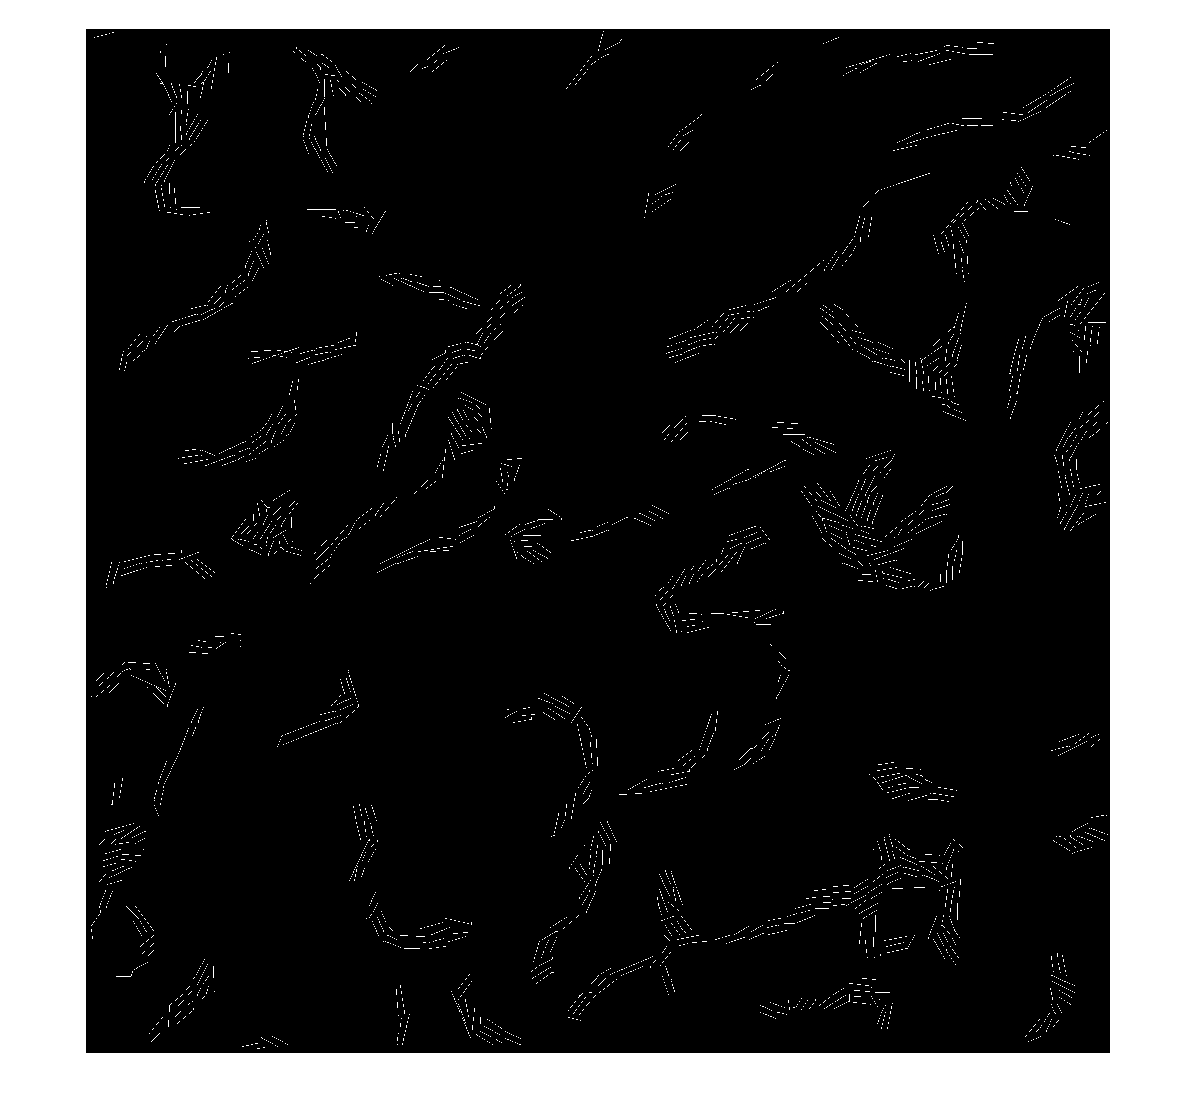

imshow(skelNew2),title ('line resconstruction')

%本来计划将细菌线性重组以后，对连通区域大于3的像素点进行人为分割 绝大多数的细菌重组的很好，但是有小部分细菌的有转弯
%但没有分叉点，重组后会与其他细菌交叉

 %进行膨胀还原，效果不好

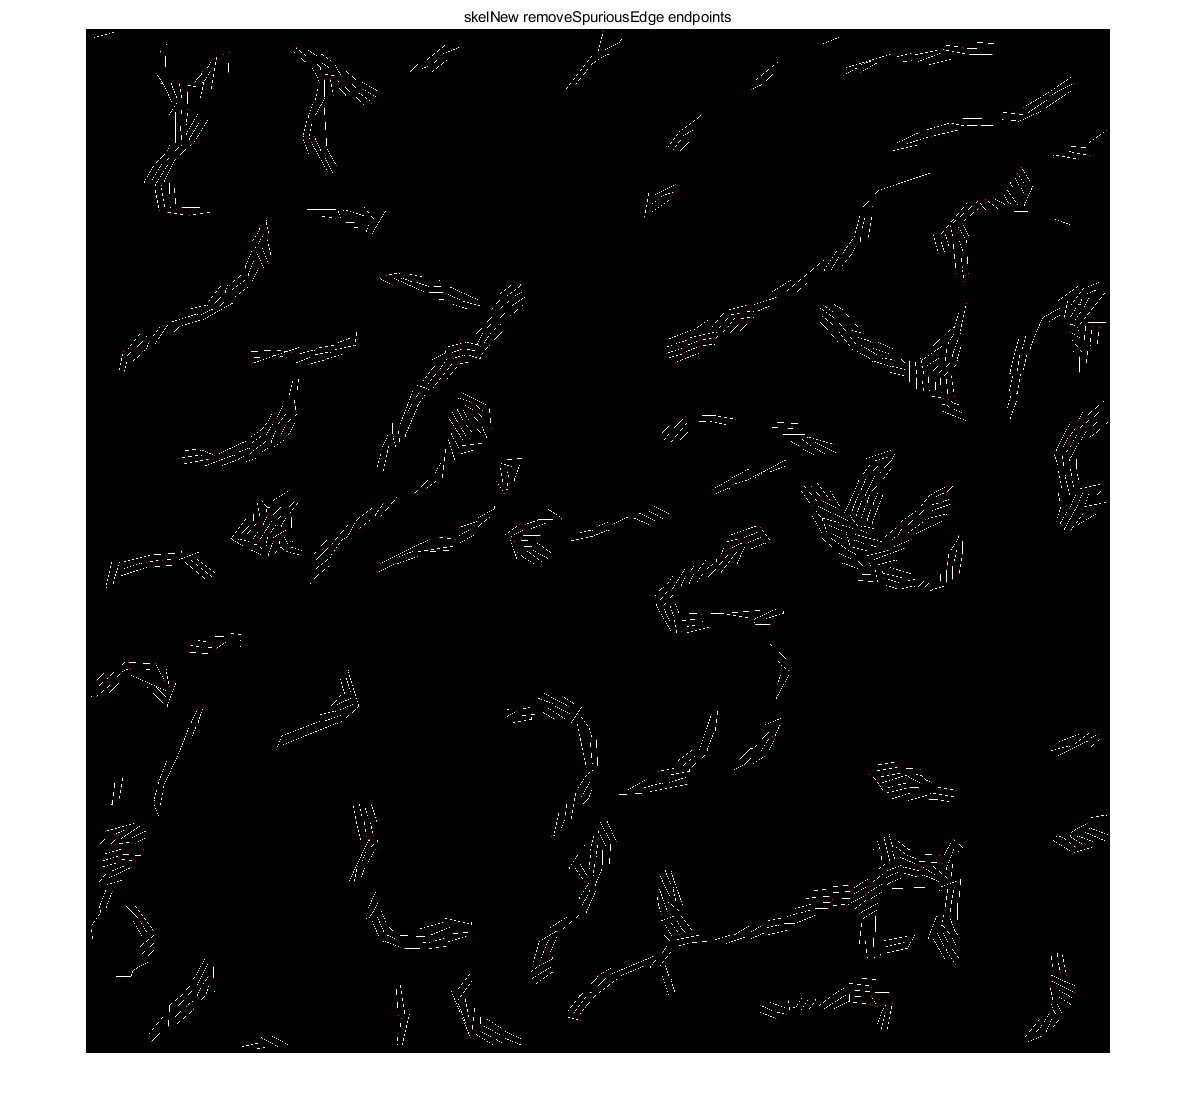

% figure, 
% B = bwmorph(skel, 'branchpoints');
% E = bwmorph(skel, 'endpoints');
% overlay1 = imoverlay(skelNew, B, [.3 1 .3]);
% imshow(overlay1), title('skelNew')
% overlay2 = imoverlay(overlay1, E, [1 0 0]);
% imshow(overlay2), title('skelNew removeSpuriousEdge')
% % 
% % E = bwmorph(skelNew, 'endpoints');
% % skelNew=skelNew&(~E); %删除endpoint 要不膨胀会连在一起
% % E = bwmorph(skelNew, 'endpoints');
% % skelNew=skelNew&(~E);
% 
B = bwmorph(skelNew, 'branchpoints');
E = bwmorph(skelNew, 'endpoints');
overlay1 = imoverlay(skelNew2, B, [.3 1 .3]);
% imshow(overlay1)
overlay2 = imoverlay(overlay1, E, [1 0 0]);
imshow(overlay2), title('skelNew removeSpuriousEdge endpoints')

% 
% se = strel('disk',3);
% reIm=imdilate(skelNew,se);
% figure,imshow(reIm),title('reIm')
% % skel_reIm = bwmorph(bw,'skel',Inf);
% % B = bwmorph(skel_reIm, 'branchpoints');
% % E = bwmorph(skel_reIm, 'endpoints');
% % overlay1 = imoverlay(skel_reIm, B, [.3 1 .3]);
% % % imshow(overlay1)
% % overlay2 = imoverlay(overlay1, E, [1 0 0]);
% % imshow(overlay2), title('reIm endbranchpoints')

test RFOVE

% bwSeg = zeros(size(reIm));
% 
% stats = regionprops(reIm,'PixelIdxList');
% pixelNum = zeros(2,numel(stats));
% for j=1:numel(stats)
%     pixelNum(1,j)=j;
%     pixelNum(2,j)=numel(stats(j).PixelIdxList);
% end
% templogic=(pixelNum(2,:)>=400);
% if sum(templogic)>0
%     stats=stats(templogic);
%     for k=1:numel(stats)
%         bwSeg(stats(k).PixelIdxList)=1;
%         tempImage=false(size(image,1),size(image,2));
%     end
% end
% 
% imshow (bwSeg),title ('bwSeg')
% CC = bwconncomp(bwSeg, 8);
% L = labelmatrix(CC);
% imshow(label2rgb(L))
% % [ IClustTotal,totEll,INITSEG] = runMainAlgoTestYs(Iobr,CC,L); % 效果不好
% % 可能对圆形的分割会好些
% % imshow(label2rgb(IClustTotal))